%% Preparación del entorno
clear;
clc;
close all;

%% Definición simbólica del sistema
syms p53 Stat3 Np63 IL4
assume(IL4 >= 0)

% Parámetros
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
Pstat3 = 0.9819;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53)*(1+IL4) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

bifurcacion = []; % Para almacenar [IL4, p53, Stat3, Np63, estabilidad]

% Variables simbólicas a resolver
vars = [p53, Stat3, Np63];

% Preparar vector de valores para IL4
IL4_vals = linspace(0, 50, 200);
resultados = [];

for i = 1:length(IL4_vals)
    valor_P = IL4_vals(i);
    soluciones = vpasolve([subs(f1, IL4, valor_P)==0, ...
                           subs(f2, IL4, valor_P)==0, ...
                           subs(f3, IL4, valor_P)==0], ...
                          [p53, Stat3, Np63]);
    
    % Convertir soluciones a vectores numéricos (puede haber varias)
    p53_sol = double(soluciones.p53);
    Stat3_sol = double(soluciones.Stat3);
    Np63_sol = double(soluciones.Np63);
    
    for j = 1:length(p53_sol)
        x1 = p53_sol(j);
        x2 = Stat3_sol(j);
        x3 = Np63_sol(j);

        % Verificar si el punto es real y no negativo
        if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
            % Construir la matriz Jacobiana en el punto
            J = jacobian([f1, f2, f3], [p53, Stat3, Np63]);
            J_num = double(subs(J, [p53, Stat3, Np63, IL4], [x1, x2, x3, valor_P]));
            autovalores = eig(J_num);
            
            % Clasificación básica de estabilidad
            if all(real(autovalores) < 0)
                tipo = "Estable";
            elseif any(real(autovalores) > 0) && any(real(autovalores) < 0)
                tipo = "Silla";
            else
                tipo = "Inestable";
            end
            
            % Guardar resultado
            resultados = [resultados; {valor_P, x1, x2, x3, tipo}];
        end
    end
end

resultados

resultados = 200×5 cell array
    {[     0]}    {[7.7238]}    {[10.7744]}    {[ 6.8384]}    {["Estable"]}
    {[0.2513]}    {[7.6721]}    {[13.4057]}    {[ 7.4852]}    {["Estable"]}
    {[0.5025]}    {[7.6307]}    {[16.0254]}    {[ 8.0894]}    {["Estable"]}
    {[0.7538]}    {[7.5965]}    {[18.6364]}    {[ 8.6588]}    {["Estable"]}
    {[1.0050]}    {[7.5676]}    {[21.2407]}    {[ 9.1988]}    {["Estable"]}
    {[1.2563]}    {[7.5429]}    {[23.8398]}    {[ 9.7137]}    {["Estable"]}
    {[1.5075]}    {[7.5214]}    {[26.4347]}    {[10.2068]}    {["Estable"]}
    {[1.7588]}    {[7.5024]}    {[29.0262]}    {[10.6806]}    {["Estable"]}
    {[2.0101]}    {[7.4856]}    {[31.6148]}    {[11.1373]}    {["Estable"]}
    {[2.2613]}    {[7.4706]}    {[34.2011]}    {[11.5786]}    {["Estable"]}
    {[2.5126]}    {[7.4570]}    {[36.7853]}    {[12.0061]}    {["Estable"]}
    {[2.7638]}    {[7.4446]}    {[39.3679]}    {[12.4210]}    {["Estable"]}
    {[3.0151]}    {[7.4333]}    {[41.9491]}    {[12.8243]}


% Convertir resultados a tabla
bifurcacion_tbl = cell2table(resultados, 'VariableNames', ...
    {'IL4', 'p53', 'Stat3', 'Np63', 'Estabilidad'});

% Mostrar una parte de la tabla
disp(head(bifurcacion_tbl, 10))

      IL4       p53      Stat3      Np63     Estabilidad
    _______    ______    ______    ______    ___________

          0    7.7238    10.774    6.8384     "Estable" 
    0.25126    7.6721    13.406    7.4852     "Estable" 
    0.50251    7.6307    16.025    8.0894     "Estable" 
    0.75377    7.5965    18.636    8.6588     "Estable" 
      1.005    7.5676    21.241    9.1988     "Estable" 
     1.2563    7.5429     23.84    9.7137     "Estable" 
     1.5075    7.5214    26.435    10.207     "Estable" 
     1.7588    7.5024    29.026    10.681     "Estable" 
     2.0101    7.4856    31.615    11.137     "Estable" 
     2.2613    7.4706    34.201    11.579     "Estable" 



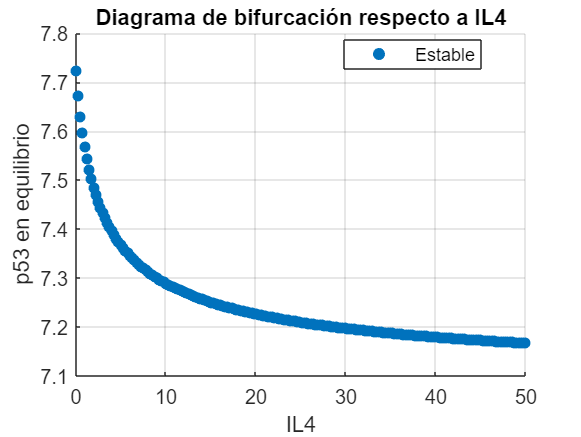


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.IL4(idx), bifurcacion_tbl.p53(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('IL4'); ylabel('p53 en equilibrio');
title('Diagrama de bifurcación respecto a IL4');
legend('Location', 'best');
grid on;

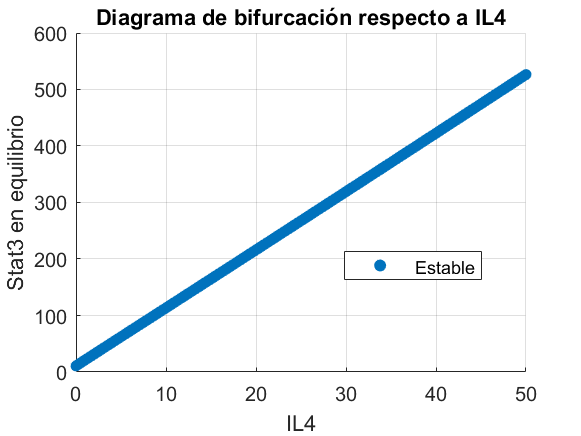



% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.IL4(idx), bifurcacion_tbl.Stat3(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('IL4'); ylabel('Stat3 en equilibrio');
title('Diagrama de bifurcación respecto a IL4');
legend('Location', 'best');
grid on;

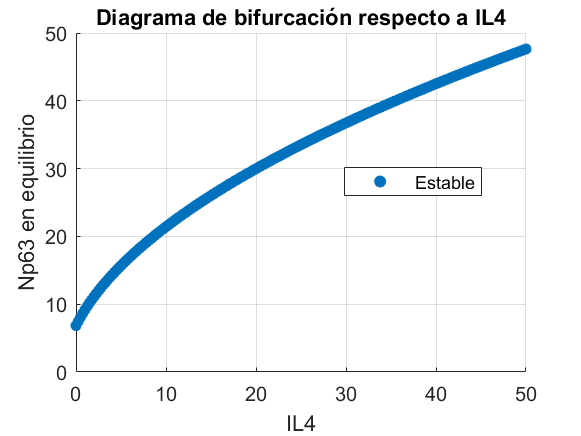


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.IL4(idx), bifurcacion_tbl.Np63(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('IL4'); ylabel('Np63 en equilibrio');
title('Diagrama de bifurcación respecto a IL4');
legend('Location', 'best');
grid on;